close all
clear all
clc         

## 一、

### （1）

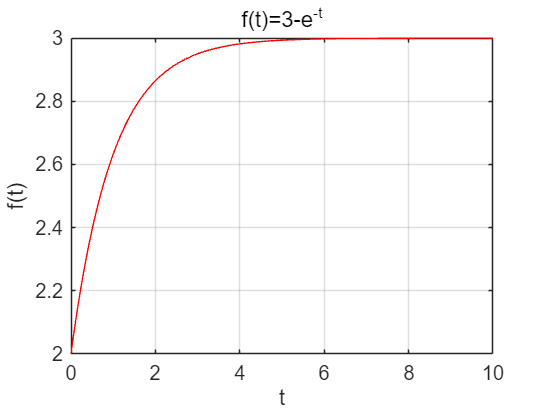

figure(1);
t1=0:0.01:10;
f1=3-exp(-t1);
plot(t1,f1,'r-');
grid on;
xlabel('t');
ylabel('f(t)');
title('f(t)=3-e^{-t}');

### (2)

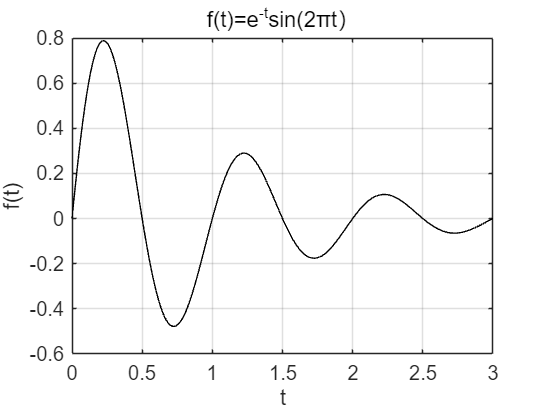

figure(2);
t2=0:0.01:3;
f2=exp(-t2).*sin(2*pi*t2);
plot(t2,f2,'k-');
grid on;
xlabel('t');
ylabel('f(t)');
title('f(t)=e^{-t}sin(2πt）');

### (3)

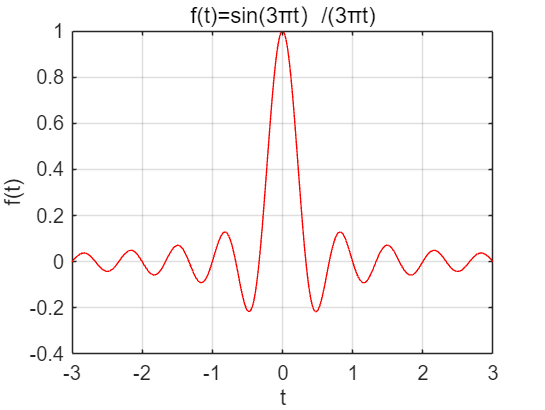

figure(3);
t3=-3:0.01:3;
f3=sin(3*pi*t3)./(3*pi*t3);
plot(t3,f3,'r');
grid on;
xlabel('t');
ylabel('f(t)');
title('f(t)=sin(3πt）/(3πt)');

### (4)

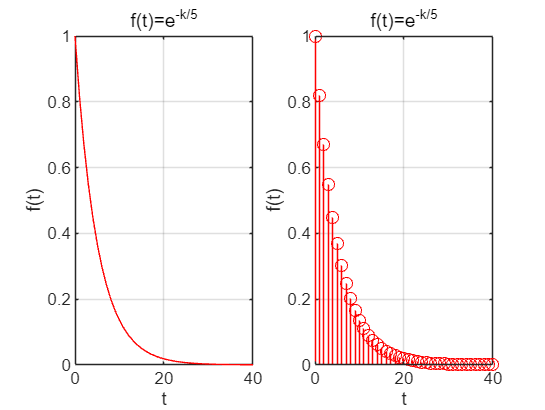

figure(4);
t4=0:40;
f4=exp(-t4/5);
subplot(1,2,1);
plot(t4,f4,'r');
grid on;
xlabel('t');
ylabel('f(t)');
title('f(t)=e^{-k/5}');
subplot(1,2,2);
stem(t4,f4,"ro");
grid on;
xlabel('t');
ylabel('f(t)');
title('f(t)=e^{-k/5}');

## 二、

### （1）

A1=[2,3,1;1,1,1;3,-1,-1];
B2=[11;6;-2];
x1=A1\B2

x1 =     1.0000
    2.0000
    3.0000


### （2)

A2=[1,1,0;0,1,1;1,0,1];
B2=[27;33;30];
x2=A2\B2

x2 =     12
    15
    18


##  三、

k=-30:30;

###  (1)

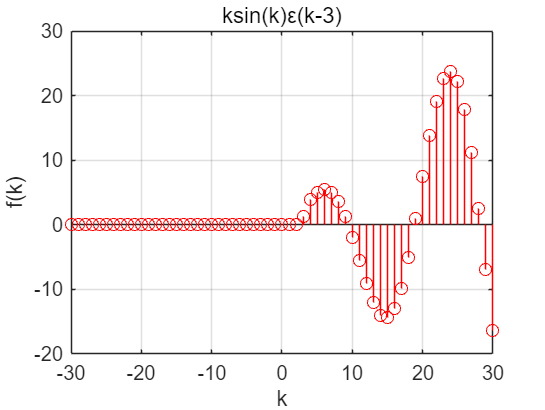

figure(5);
f5=k.*sin(k./3).*heaviside(k-3);
stem(k,f5,'r');
grid on;
xlabel('k');
ylabel('f(k)');
title('ksin(k)ε(k-3)');

###  (2)

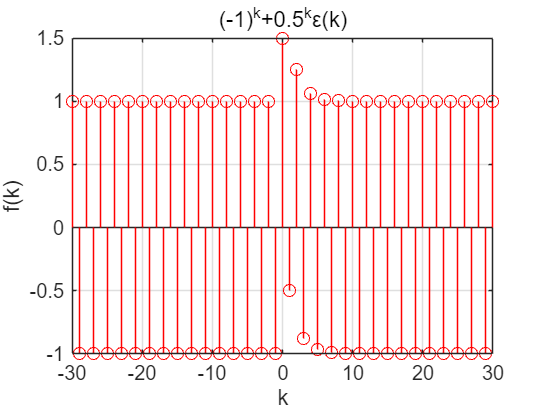

figure(6);
f6=(-1).^k+(0.5).^k.*heaviside(k);
stem(k,f6,'r');
grid on;
xlabel('k');
ylabel('f(k)');
title('(-1)^{k}+0.5^{k}ε(k)');

## 四、

###  (1)

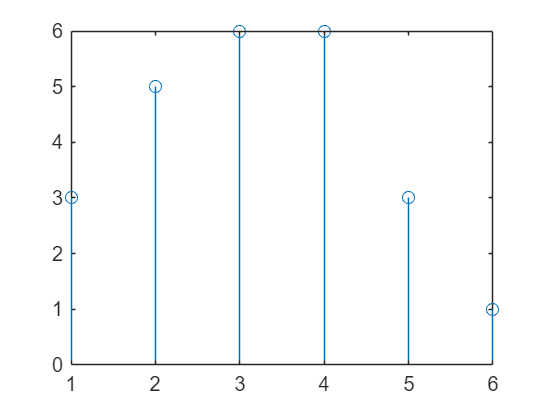

figure(7);
f1_1=[1,1,1,1];
f1_2=[3,2,1];
conv2=conv(f1_1,f1_2);
stem(conv2);

### (2)

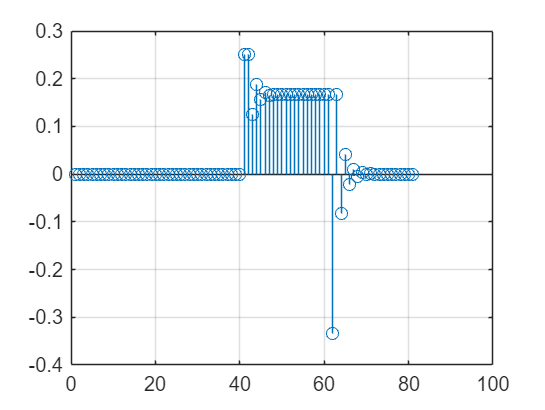

figure(8);
k2=-20:1:20;
f2_1=heaviside(k2);
f2_2=(-0.5).^k2.*heaviside(k2);
conv3=conv(f2_1,f2_2);
stem(conv3);
grid on;

## 五、

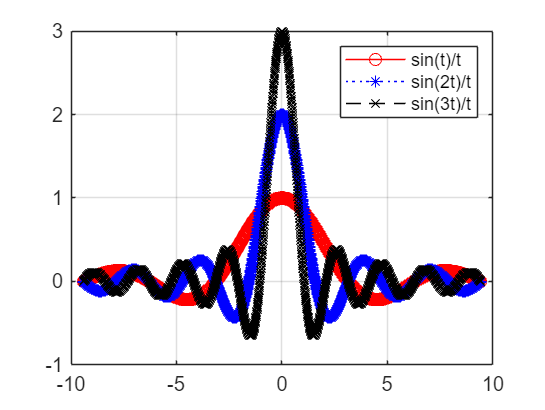

figure(9);
t=-3*pi:0.01:3*pi;
f5_1=sin(t)./t;
f5_2=sin(2*t)./t;
f5_3=sin(3*t)./t;
plot(t,f5_1,"r-o",t,f5_2,"b:*",t,f5_3,"k--x","LineWidth",0.5);
grid on;
legend('sin(t)/t','sin(2t)/t','sin(3t)/t');

## 六、

t_6=-5:0.01:5;

### (1)

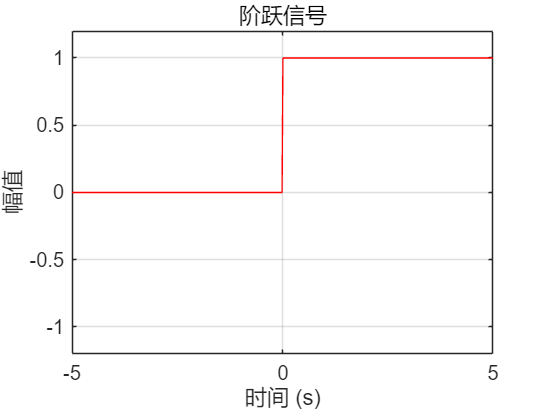

figure(10);
f6_1=heaviside(t_6);
plot(t_6,f6_1,"r");
axis([-5 5 -1.2 1.2]);
title('阶跃信号');
xlabel('时间 (s)');
ylabel('幅值');
grid on;

### (2)

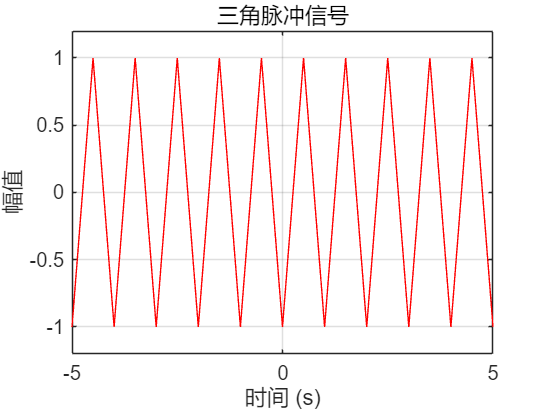

figure(11);
f6_2=sawtooth(2*pi*t_6,0.5);
plot(t_6,f6_2,"r");
axis([-5 5 -1.2 1.2]);
title('三角脉冲信号');
xlabel('时间 (s)');
ylabel('幅值');
grid on;

### (3)

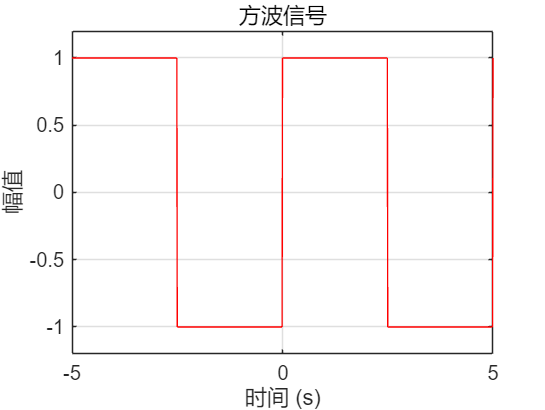

figure(12);
f6_3=square(2*pi*0.2*t_6);
plot(t_6,f6_3,"r");
axis([-5 5 -1.2 1.2]);
title('方波信号');
xlabel('时间 (s)');
ylabel('幅值');
grid on;

### (4)

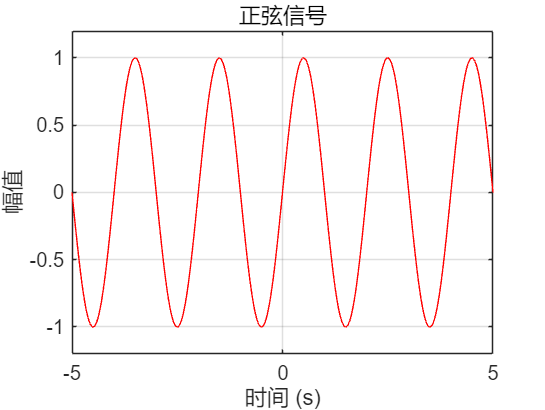

figure(13);
f6_4=sin(2*pi*0.5*t_6);
plot(t_6,f6_4,"r");
axis([-5 5 -1.2 1.2]);
title('正弦信号');
xlabel('时间 (s)');
ylabel('幅值');
grid on;